# Example 4.2: Maximum Detection Range of an LPI Radar Pulse

Nicholas O'Donoughue 1 July 2019

*Consider detection of an **LPI** radar pulse, whose parameters are given in Table 4.2a. Parameters for a receiver are given in Table 4.2b.*

*What is the maximum detection range for an energy detector and a cross-correlation detector on the provided radar and detector when the radar is (a) pointed at the detector *$$\left(G_t = 30\ \mathrm{dBi}\right)$$*, (b) pointed near the detector *$$\left(G_t = 10\ \mathrm{dBi}\right)$$*, or (c) pointed far away from the detector *$$\left(G_t = 0\ \mathrm{dBi}\right)$$*?  Assume that the maximum acceptable *$$P_{\mathrm{FA}}$$* is *$$10^{-6}$$*, and that the desired *$$P_{\mathrm{D}}$$* is 0.8.*

## Solution

First, we define the parameters

% Transmit Side
Pt = 10*log10(500);
f0 = 16e9;
ht = 6096;
Lt = 3;
Bs = 200e6;
Tp = 20e-6;
Gt = [30,10,0];

% Receive Side
hr = 20;
Gr = 0;
Lr = 3;
NF = 4;
Bn = 500e6;
Tcorr = 1e-4;


Next, we compute the initial SNR ($\xi_0$) without propagation losses.

% Compute xi0
N0 = utils.constants.boltzmann*utils.constants.T0*10^(NF/10);
N = 10*log10(N0*Bn);
xi0 = Pt+Gt + Gr - Lt - Lr - N;

% Adjust xi0 to account for partial pulse
xi0 = xi0 + 10*log10(min(1,Tp/Tcorr))

xi0 =   156.9856  136.9856  126.9856


We follow a similar approach with the radar pulse as was done with the communications pulse. First, the detection thresholds for the energy detector and cross-correlation detector are computed.

% Compute thresholds
PD=.8;
PFA=1e-6;
M = fix(Tcorr*Bn);
xi_ed = detector.squareLawMinSNR(PFA,PD,M)

xi_ed = -15.9756

xi_xc = detector.xcorrMinSNR(PFA,PD,Tcorr,Tp,Bn,Bs)

xi_xc = -22.4984

Next, we compute the max detection range analytically.

% Compute Max Range
R_ml_ed = detector.squareLawMaxRange(PFA,PD,M,f0,ht,hr,xi0(1),false,[]);
R_nearSL_ed = detector.squareLawMaxRange(PFA,PD,M,f0,ht,hr,xi0(2),false,[]);
R_farSL_ed = detector.squareLawMaxRange(PFA,PD,M,f0,ht,hr,xi0(3),false,[]);
R_ml_xc = detector.xcorrMaxRange(PFA,PD,Tcorr,Tp,Bn,Bs,f0,ht,hr,xi0(1),false,[]);
R_nearSL_xc = detector.xcorrMaxRange(PFA,PD,Tcorr,Tp,Bn,Bs,f0,ht,hr,xi0(2),false,[]);
R_farSL_xc = detector.xcorrMaxRange(PFA,PD,Tcorr,Tp,Bn,Bs,f0,ht,hr,xi0(3),false,[]);

fprintf('Mainlobe detection\n\tusing Energy Detector: %.2f km\n\tusing Cross Correlator: %.2f km\n',R_ml_ed/1e3,R_ml_xc/1e3);

Mainlobe detection
	using Energy Detector: 663.05 km
	using Cross Correlator: 1404.76 km


fprintf('Near sidelobe detection\n\tusing Energy Detector: %.2f km\n\tusing Cross Correlator: %.2f km\n',R_nearSL_ed/1e3,R_nearSL_xc/1e3);

Near sidelobe detection
	using Energy Detector: 66.31 km
	using Cross Correlator: 140.49 km


fprintf('Far sidelobe detection\n\tusing Energy Detector: %.2f km\n\tusing Cross Correlator: %.2f km\n',R_farSL_ed/1e3,R_farSL_xc/1e3);

Far sidelobe detection
	using Energy Detector: 20.97 km
	using Cross Correlator: 44.39 km


Finally, to compare with the analytic results, we compute the received SNR as a function of range, and plot the result for mainlobe detection, near-in sidelobe detection, and distant sidelobe detection.

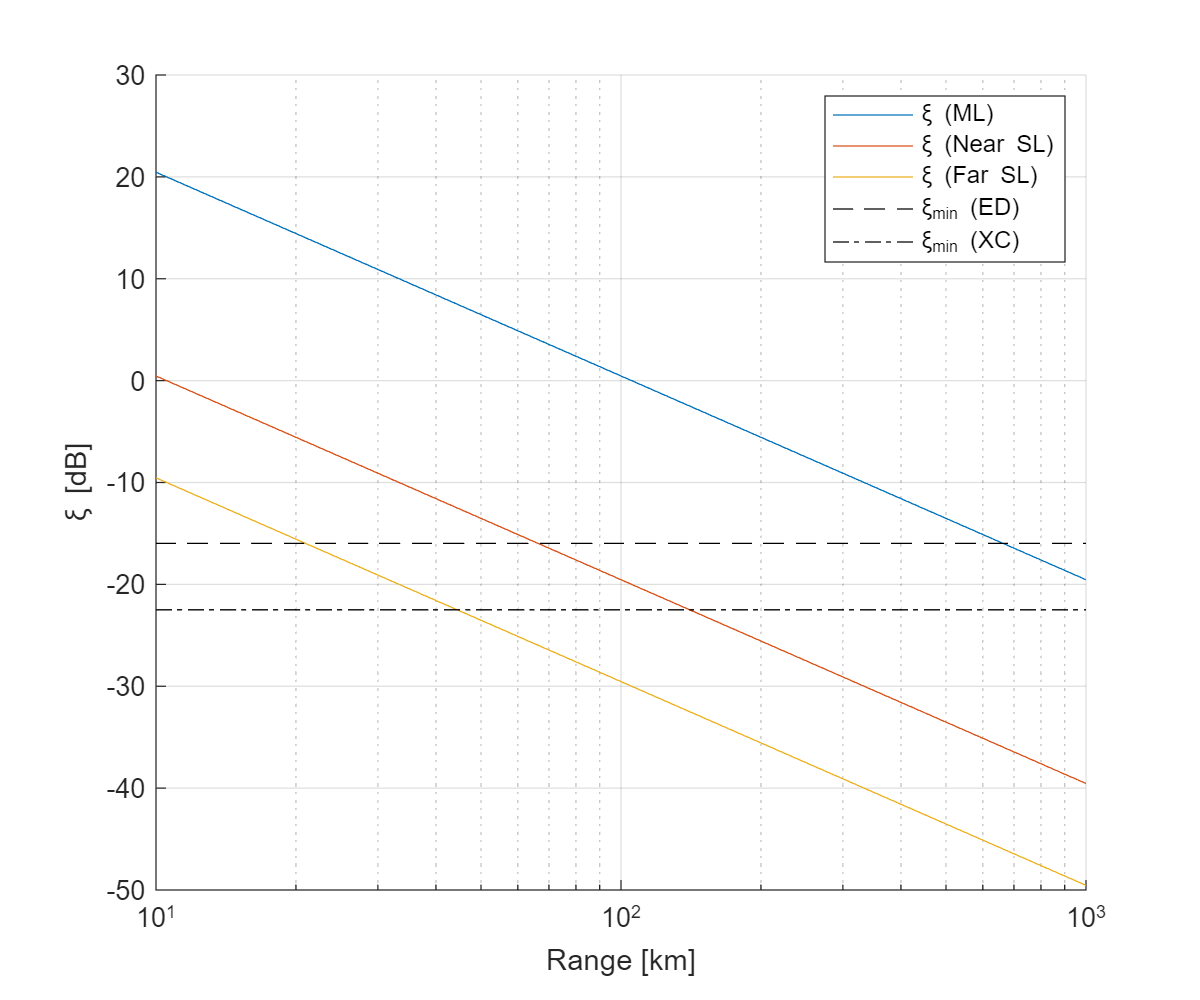

% Compute Prop Loss
min_range_km = 10; % km
max_range_km = 1000; % km
step_km = 10; % km
Rvec = (min_range_km:step_km:max_range_km)*1e3; % m
Lprop = prop.pathLoss(Rvec,f0,ht,hr,false);

xi = xi0(:) - Lprop;

% Plot results
fig=figure;
hold on;
legendCell = {'\xi (ML)','\xi (Near SL)','\xi (Far SL)'};
for i=1:numel(Gt)
    plot(Rvec/1e3,xi(i,:),'DisplayName',legendCell{i});
end
plot(Rvec([1 end])/1e3,xi_ed*[1 1],'k--','DisplayName','\xi_{min} (ED)');
plot(Rvec([1 end])/1e3,xi_xc*[1 1],'k-.','DisplayName','\xi_{min} (XC)');
legend;
grid on;
xlabel('Range [km]');
ylabel('\xi [dB]');
set(gca,'xscale','log');